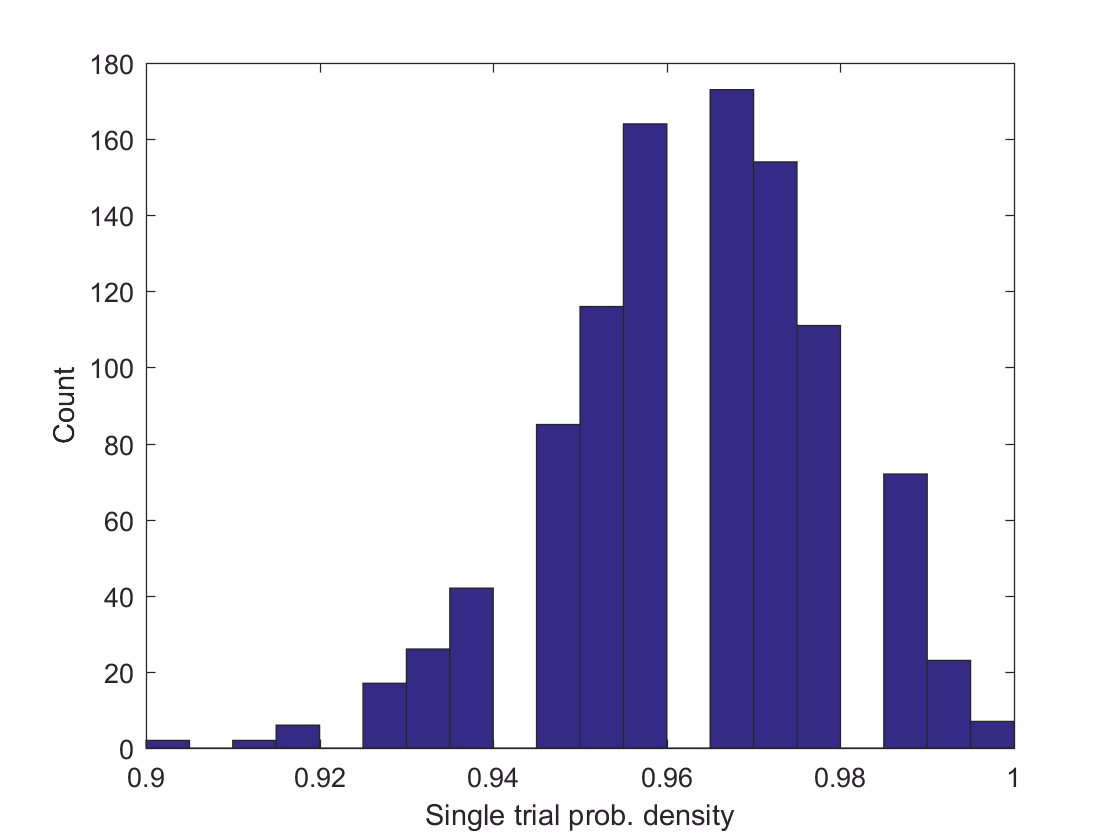

% binomial pdf test
% simulate a bin in a pdf histogram to get the 
% standard error and compare with the formula
% simulated distribution is flat in [0, 1)
nsim = 1000; % number of simulations
N = 150; % number of trials in each simulation
w = 1; % bin width
% ni = (sum(rand(N, nsim) < w)); % flat distribution
ni = (sum(exprnd(0.3, N, nsim) < w)); % exponential dist.
pdf = ni ./ (N .* w);
hist(pdf,20)
xlabel('Single trial prob. density')
ylabel('Count')

disp('Single trial estimate prob. density')

Single trial estimate prob. density


disp(pdf(1))

    0.9933



disp('Simulated prob. density')

Simulated prob. density


disp(mean(pdf))

    0.9639



disp('Single trial estimate s.e. of prob density')

Single trial estimate s.e. of prob density


p = ni(1) ./ N;
disp(sqrt(N * p * (1-p)) ./  (N .* w))

    0.0066



disp(sqrt(p .* (1-p) ./ N)./ w) % just verifying that the version in binned_pdf.m is correct

    0.0066



disp('Simulated s.e. of prob. density')

Simulated s.e. of prob. density


disp(std(pdf))

    0.0157

